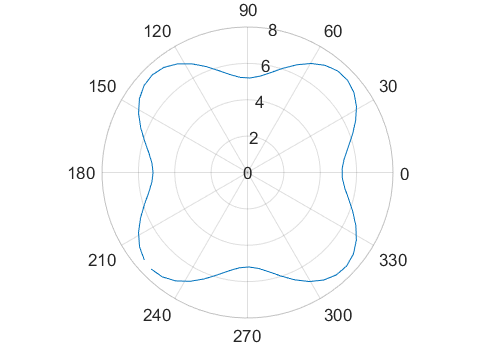

[x, y] = clover(pi/4,1);


%¿Cuántos cm quiere desplazar el trébol desde su punta inferior?
trasl = 10

trasl = 10

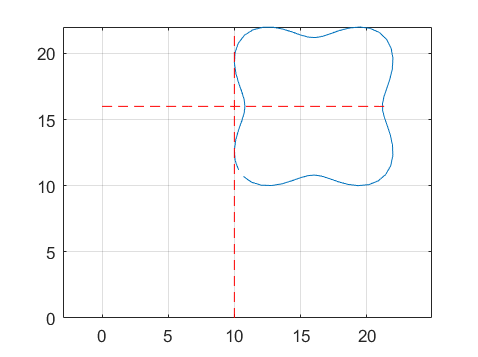

[x, y] = cloverCartesian(x, y, trasl);

th1 = 106.8110

th3 = -16.8021

f2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


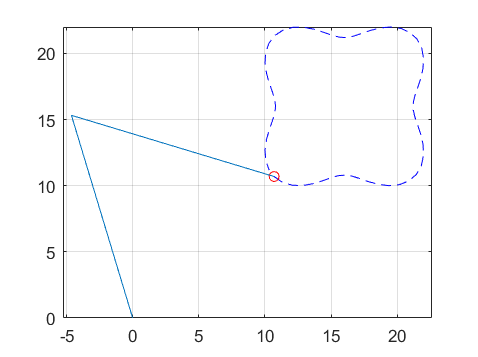


%Distancia total 
longitudTotal = sqrt((max(x)-min(x))^2+((max(y)-min(y))^2))...
                + sqrt(trasl^2*2);
%Información de los brazos
l1 = 16;
l2 = 16;

function [x, y] = clover(phi, A)
    B = 5.5;
    theta = 0:0.1:2*pi;
    theta = theta - 2.356;
    radio = (B + cos(4.*(theta-phi)))*7.5/(B+1)*A;
    polarplot(theta, radio);
    hold off

    x = radio.*cos(theta);
    y = radio.*sin(theta);
end

function [x, y] = cloverCartesian(x, y, trasl)
    maxX = max(x);
    maxY = max(y);

    x = x+maxX+trasl;
    y = y+maxY+trasl;

    horX = [0:0.5:maxX*2+trasl];
    horY = (maxY+trasl)*ones(length(horX));

    vertY = [0:0.5:maxY*2+trasl];
    vertX = trasl*ones(length(vertY));

    f1 = figure(1);
    plot(x, y);
    hold on;
    plot(horX, horY, "--r");
    plot(vertX,vertY, "--r");
    axis equal;
    grid on;
    hold off;

end

function [th1, th3] = position(x,y,l1,l2, thGuess)

    error = 1e-5;
    NF = 1e-5*1000;
    
    while error < abs(NF)
        th1 = thGuess(1);
        th3 = thGuess(2);

        h = sqrt(x^2+y^2);
        phi = atand(y/x);
    
        F = [l1*cosd(th1) + l2*cosd(th3) - h*cosd(phi);
            l1*sind(th1) + l2*sind(th3) - h*sind(phi)];

        J = [-l1*sind(th1), -l2*sind(th3);
            l1*cosd(th1), l2*cosd(th3)];
        Dth = J\(-F);
        
        NF = norm(F);
        thGuess = Dth +thGuess;
    end

end


function animation()
    
    thGuess = [80; 40];
    [th1, th3] = position(x(1),y(1),l1,l2,thGuess)
    
    %Posición de cada una de las juntas
    A = [0,0];
    B = [A(1) + l1*cosd(th1), A(2) + l1*sind(th1)];
    C = [B(1) + l2*cosd(th3), B(2) + l2*sind(th3)];
    
    xJunta = [A(1), B(1), C(1)];
    yJunta = [A(2), B(2), C(2)];
    
    f2 = figure(2)
    plot(x, y, "--b")
    hold on
    plot(x(1), y(1), "or")
    line(xJunta, yJunta)
    axis equal
    grid on



end
